## Import ISONE hourly demand data

% Import ISONE hourly demand data in the 2019 whole year
% Run this under the model_code directory or change the genFileDir manually
demandFileDir = "..\data\2019_DEMAND_ISONE\";
demandFileName = "da_hourlydemand_2019*.csv";
demandDataStore = fileDatastore(demandFileDir + demandFileName, "ReadFcn", @importDemandISONE, "UniformRead", true);
demandAll = readall(demandDataStore);
clear demandDataStore;

Calculate daily demand

dailyDemand = groupsummary(demandAll, "Date", "sum", "DayAheadDemand");
dailyDemand = removevars(dailyDemand, "GroupCount");
dailyDemand.Properties.VariableNames = ["Date", "Demand"];
dailyDemand.Demand = dailyDemand.Demand/1000;

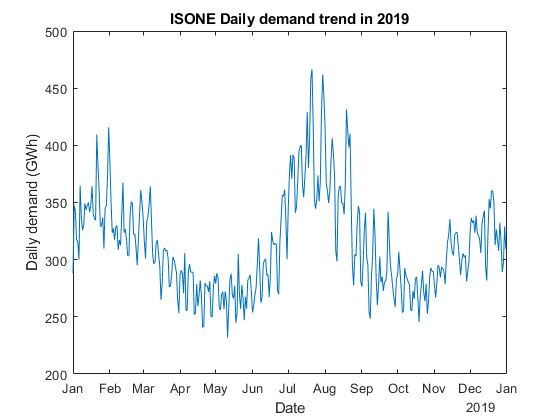

plot(dailyDemand.Date, dailyDemand.Demand);
xlabel("Date");
ylabel("Daily demand (GWh)");
title("ISONE Daily demand trend in 2019");
saveas(gcf, "../model_output/figures/dailyDemand.png");